## Matlab code for generateing main figs in the following paper:

Shuxiong Wang, et al., **single cell trascriptomics of human epidermis reveals basal stem cell transition states**, *nature communications (to appear)*, 2020

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('EE');
addpath('vinlinplot');
addpath('scTools');
addpath('scTools/graphViz2Mat1');

% Set the folder to save all figures
folder = 'Results';

#### Step 1 (Required)

Load data

%% Step 1: load data
load data_integration_results.mat;

#### Step 2 (Optional) -- skip this step to save time

We have done this step and saved the results in **data_integration_results.mat**

%% Step 2-1: Run SoptSC to identify clusters from the integrated data (libraries 1-5)
% go to step 2 and direct load the results generate all the plots in the following steps
tic;
NC = 7;   % if NC = [], the algorithm predict the number of clusters 
No_exc_cell = 0;
No_features = 5000;
[W,No_cluster,cluster_label,H,eigenvalues] = SoptSC_cluster(full(data_integrated),NC,No_exc_cell,No_features);
running_time = toc;

%% construct cell-cell graph and embed cells using gephi
% more details on gehpi can be found: 
% https://www.mathworks.com/matlabcentral/fileexchange/4518-matlab-graphviz-interface
% or STITCH
% https://github.com/wagnerde/STITCH

adjacentM = abs(W) + abs(W');
bg = graph(adjacentM); 
graph_to_dot(adjacency(bg), 'directed', 0, 'filename', 'gephi/latent_all.dot');

%% import graph embeding from gephi
latent_all = import_gephi_xy('gephi/latent_all.net');

#### Skip step 2-2

%% Step 2-2: Run SoptSC to identify clusters for keratinocyte cells
tic;
NCr = 7;   
No_exc_cell = 0;
No_features = 5000;
[Wr,No_clusterr,cluster_labelr,Hr,eigenvaluesr] = SoptSC_cluster(full(data_integrated(:,krt_idx)),NCr,No_exc_cell,No_features);
running_time1 = toc;

%%
epsilon = 0.5; 
adjacentM = abs(Wr) + abs(Wr');
adjacentM = adjacentM./max(adjacentM(:));
adjacentM(adjacentM < epsilon) = 0;

bg = graph(adjacentM); 
graph_to_dot(adjacency(bg), 'directed', 0, 'filename', 'gephi/latentr.dot');

%% import graph embeding from gephi
latentr = import_gephi_xy('gephi/latentr.net');

#### Skip step 2-3

%% Step 2-3: Run SoptSC to identify clusters for basal cells
NCb = 7;   
No_exc_cell = 0;
No_features = 2000;
[Wb,No_clusterb,cluster_labelb,Hb,eigenvaluesb] = SoptSC_cluster(data_basal,NCb,No_exc_cell,No_features);

%%
epsilon = 0.4; 
adjacentM = abs(Wb) + abs(Wb');
adjacentM = adjacentM./max(adjacentM(:));
adjacentM(adjacentM < epsilon) = 0;
bg = graph(adjacentM); 
graph_to_dot(adjacency(bg), 'directed', 0, 'filename', 'gephi/latent_basal.dot')

latent_basal = import_gephi_xy('gephi/latent_basal.net');

#### Step 3: Generating all mian figures in the paper

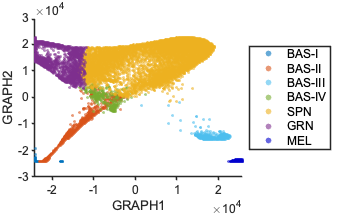

% Fig1B
figname = 'Fig1B';
method = 'GRAPH';
cluster_order = 1:No_cluster; % cluster orders for plots

plot_cluster(latent_all,cluster_label,No_cluster,lgd,folder,cluster_order,method,figname,cluster_color);

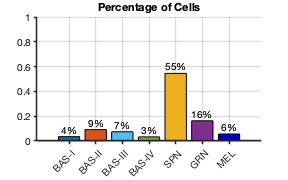

% Fig1B: percentage of cells in each cluster
figname = 'Fig1B';
cluster_order = 1:No_cluster; % cluster orders for plots

Plot_No_of_Cells(cluster_label,lgd,folder,cluster_order,cluster_color,figname);

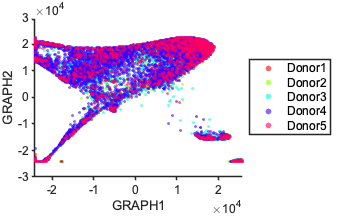

% Fig1C
lgd_batch = {'Donor1','Donor2','Donor3','Donor4','Donor5'};
figname = 'Batch_ID';
method = 'GRAPH';        % set method as 'pca' or 'tsne'
No_cluster1 = max(batch_id);
batch_order = 1:No_cluster1;

plot_cluster(latent_all,batch_id,No_cluster1,lgd_batch,folder,batch_order,method,figname,cluster_batch_color);

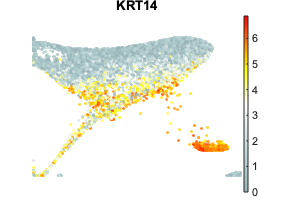

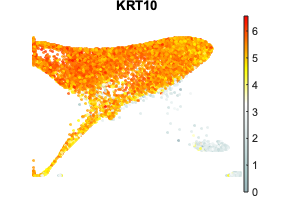

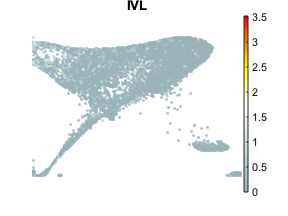

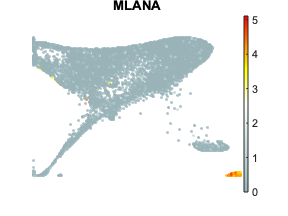

% Fig1E, feature plots
Marker = {'KRT14', 'KRT10','IVL', 'MLANA', };

plot_feature(data_all,Marker,allgenes,latent_all,folder);

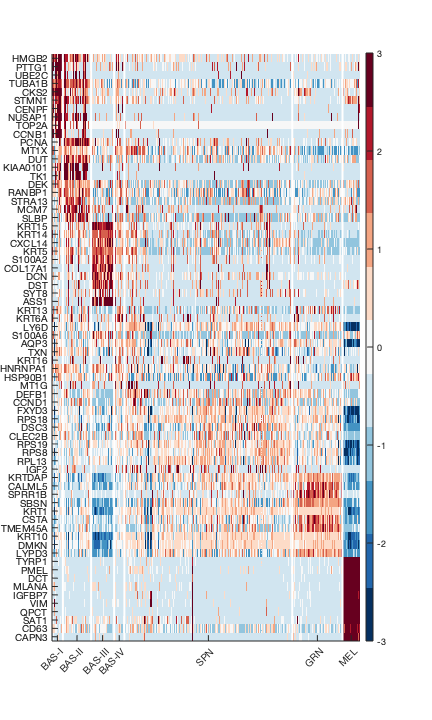

% Fig2A, gene-cell heatmap of top markers
figname = 'Fig2A';
topn = 10;
GC_htmp_DE_lgd(data_all,allgenes,cluster_label,topn,lgd,figname,folder,folder);

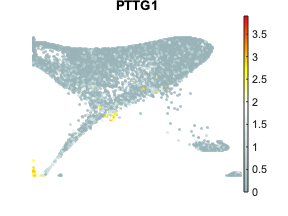

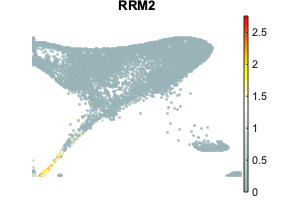

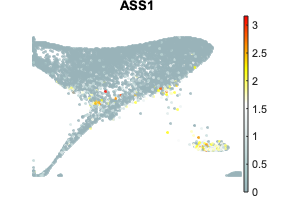

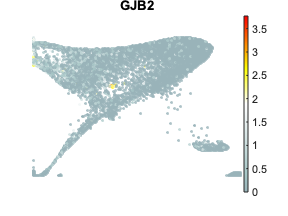

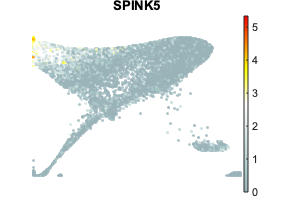

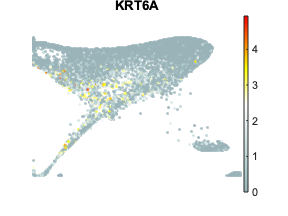

% Fig2D, feature plots
Marker = {'PTTG1', 'RRM2','ASS1','GJB2','SPINK5','KRT6A'};
plot_feature(data_all,Marker,allgenes,latent_all,folder);

### Plots for Fig4

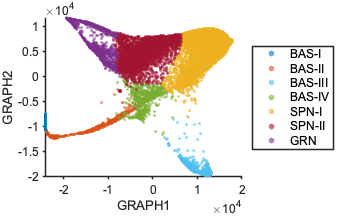

% Fig4A
figname = 'Fig4A';
method = 'GRAPH';
cluster_order = 1:No_clusterr; % cluster orders for plots
plot_cluster(latentr,cluster_labelr,No_clusterr,lgdr,folder,cluster_order,method,figname,cluster_color_r);

%% cutoff on the similarity matrix: Wr
Wr1 = Wr./max(Wr(:));
Wr1(Wr1 <= 0.5) = 0;

%% infer pseudotime and cell lineage
root_cluster = 1; % set by user, set root_cluster = 0 if the root cluster is not provided
root_cell = 7811; % set by user, set root_cell = 0 if the root cell is not provided
reverse = 0;      % reverse = 0: no reverse for the graph; reverse = 1: reverse the inferred graph  
[Lineage,pseudotime0,Cluster_cluster_adjacent] = Lineage_Ptime(Wr1,No_clusterr,cluster_labelr,...
    root_cluster,root_cell,latentr,reverse);

%% custermized setting for ptime
pseudotime = max(pseudotime0) - pseudotime0;

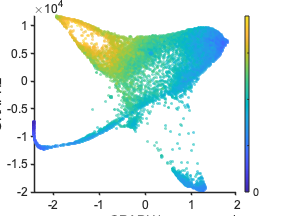

% Fig4B
figname = 'Fig4B';
method = 'GRAPH';
plot_pseudotime(latentr,pseudotime,folder,figname,method);

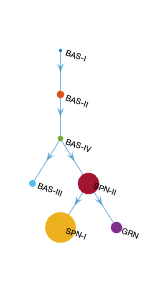

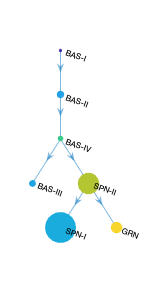

%
figname = 'lineage_tree';
plot_lineage(Lineage,No_clusterr,cluster_labelr,pseudotime,lgdr,folder,cluster_color_r,figname);

%% cutoff for cluster-cluster adjacent matirx
CC_adjacent1 = Cluster_cluster_adjacent./max(Cluster_cluster_adjacent(:));
CC_adjacent1(CC_adjacent1 <= 0.3) = 0;

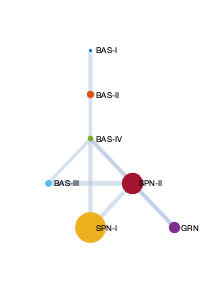

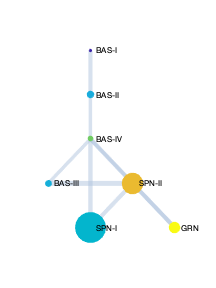

%% plot lineage by adding some new edges
No_added_edges = 3;
plot_lineage_weighted_all_edge(Lineage,No_clusterr,cluster_labelr,pseudotime,CC_adjacent1,lgdr,No_added_edges,figname,folder,cluster_color_r);

% calculate energy for each cell
P = Hr'./sum(Hr,2)';
Energy = entropy(P);

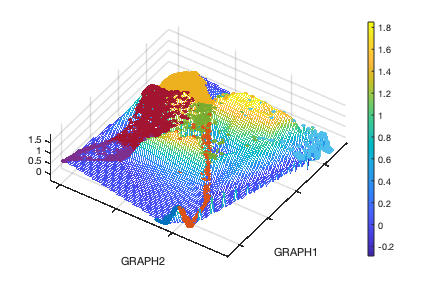

% Fig4D
figname = 'LandScape_Cells';
method = 'GRAPH';
plot_landscape(latentr,Energy,cluster_labelr,cluster_color_r,folder,figname,method);

%% Energy value for each cluster
for i = 1:No_clusterr
    E_plus_state(i) = mean(Energy(cluster_labelr==i));
end

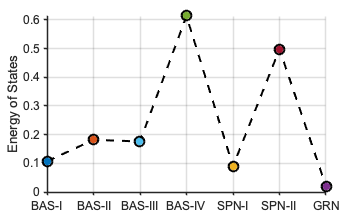

% Fig4E2
figname = 'State_Energy';
order = 1:length(lgdr);
plot_state_energy(E_plus_state,order,lgdr,cluster_color_r,figname,folder);

% Fig4H, feature plots
Marker = {'UHRF1','HELLS'};
plot_feature(datar,Marker,allgenes,latentr,folder);

Unrecognized function or variable 'allgenes'.

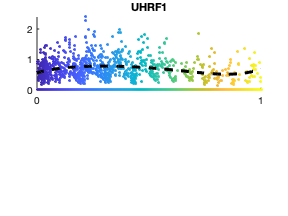

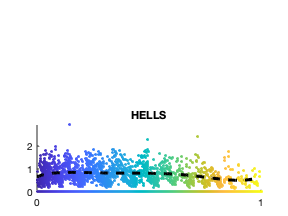

% plot marker dynamics along pseudotime
for i = 1:2
    figure(i);
    plot_gene_along_ptime(datar,Marker(i),pseudotime,allgenes,folder);
end

### Plots for Fig5 (Basal Sub-clustering)

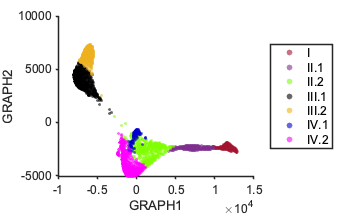

% Fig5A
figname = 'Fig5A';
method = 'GRAPH';
cluster_order = 1:No_clusterb; % cluster orders for plots
plot_cluster(latent_basal,cluster_label_basal,No_clusterb,lgd_basal,folder,cluster_order,method,figname,cluster_color_basal);

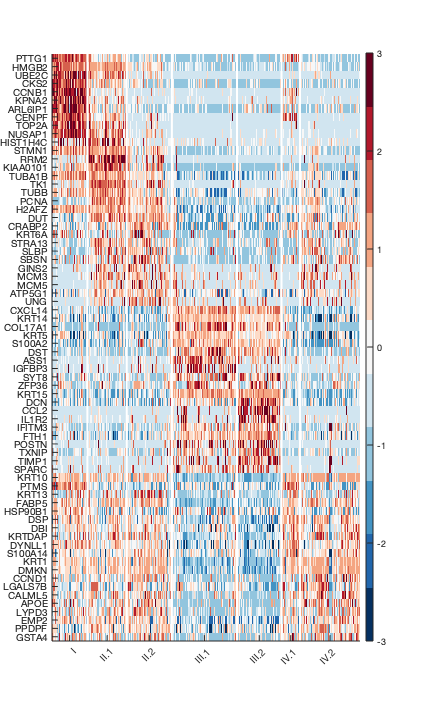

% Fig2A, gene-cell heatmap of top markers
figname = 'Fig5B';
topn = 10;
GC_htmp_DE_lgd(data_basal,allgenes,cluster_label_basal,topn,lgd_basal,figname,folder,folder);

%%
alpha = 0.2;
Wb1 = Wb./max(Wb(:));
Wb1(Wb1 <= alpha) = 0;

%%
root_cluster = 0;
root_cell = 0;
reverse = 1;
[Lineageb, pseudotimeb,CC_adjacentb] = Lineage_Ptime(Wb1,No_clusterb,cluster_label_basal,...
    root_cluster,root_cell,latent_basal,reverse); 

nComponents = 1

Root cluster candidates:
     1     5

Inferred root cell is:


root_cell = 1

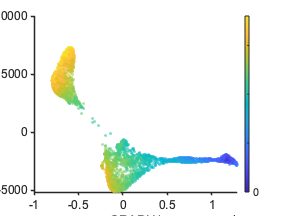

%% Fig5D
figname = 'Fig5D';
plot_pseudotime(latent_basal,pseudotimeb,folder,figname,method);

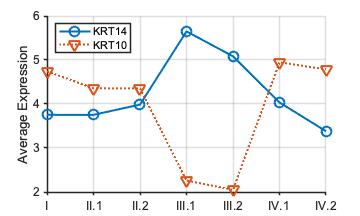

% Fig5F
figname = 'Fig5F';
Marker = {'KRT14';'KRT10'};

%%
[~,~,Mk_idx] = intersect(Marker,allgenes,'stable');
data_mk = data_basal(Mk_idx,:);
Mk_in_list = allgenes(Mk_idx);

data_mk1_mean = data_mk(1,:);
data_mk2_mean = data_mk(2,:);

%% average with each cluster
for i = 1:length(unique(cluster_labelb1))
    data_mk1_mean_C(i) = mean(data_mk1_mean(cluster_label_basal==i));
    data_mk2_mean_C(i) = mean(data_mk2_mean(cluster_label_basal==i));
end

order = 1:length(lgd_basal);
plot_KRT1014(lgd_basal,Marker,order,data_mk1_mean_C,data_mk2_mean_C,folder,figname);